# DYSKR

%INPUTS___________________________________________
A = [0 1; -6 -5];
B = [0; 6];
C = [1 0];
D = 0;
x0 = [0; 1];
h = 0.5;
t = 0:0.1:2;
i_max = max(t/h);

syms t_s;
syms h_s
disp("Analityc solution")

Analityc solution


y = expm(A.*t_s)*x0

$$y = \left(\begin{array}{c} {\mathrm{e}}^{-2\,t_{s}}-{\mathrm{e}}^{-3\,t_{s}}\\ 3\,{\mathrm{e}}^{-3\,t_{s}}-2\,{\mathrm{e}}^{-2\,t_{s}} \end{array}\right)$$

disp("Analityc dicrete matrix")

Analityc dicrete matrix


A_plus_s = expm(A.*h_s)

$$A\_plus\_s = \left(\begin{array}{cc} 3\,{\mathrm{e}}^{-2\,h_{s}}-2\,{\mathrm{e}}^{-3\,h_{s}} & {\mathrm{e}}^{-2\,h_{s}}-{\mathrm{e}}^{-3\,h_{s}}\\ 6\,{\mathrm{e}}^{-3\,h_{s}}-6\,{\mathrm{e}}^{-2\,h_{s}} & 3\,{\mathrm{e}}^{-3\,h_{s}}-2\,{\mathrm{e}}^{-2\,h_{s}} \end{array}\right)$$

B_plus_s = inv(A)*(expm(A*h_s) - eye(2, 2))*B

$$B\_plus\_s = \left(\begin{array}{c} 2\,{\mathrm{e}}^{-3\,h_{s}}-3\,{\mathrm{e}}^{-2\,h_{s}}+1\\ 6\,{\mathrm{e}}^{-2\,h_{s}}-6\,{\mathrm{e}}^{-3\,h_{s}} \end{array}\right)$$

A_plus = subs(A_plus_s, h_s, h);
%A_plus = double(A_plus)
B_plus = subs(B_plus_s, h_s, h);
%B_plus = double(B_plus)

syscmodel = ss(A, B, C, D);
sysdmodel = c2d(syscmodel,h);
disp("Discrete numeric model")

Discrete numeric model


A_discr = sysdmodel.A

A_discr =     0.6574    0.1447
   -0.8685   -0.0664


B_discr = sysdmodel.B

B_discr =     0.3426
    0.8685


C_discr = sysdmodel.C

C_discr =      1     0


D_discr = sysdmodel.D

D_discr = 0

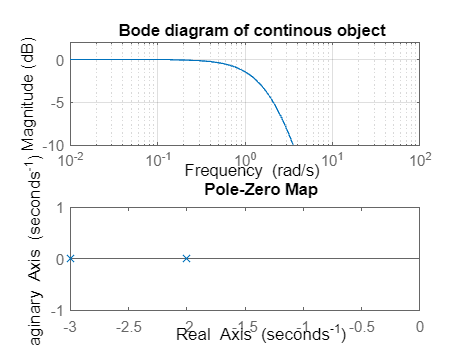


figure;
subplot(2, 1, 1)
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-10 2]};
bode(syscmodel,opts1), grid on, hold all
title("Bode diagram of continous object")
subplot(2, 1, 2)
pzmap(syscmodel)

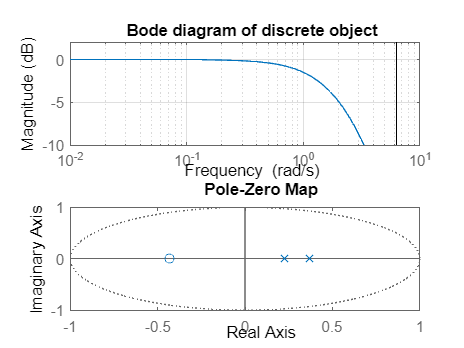


figure;
subplot(2, 1, 1)
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-10 2]};
bode(sysdmodel,opts1), grid on, hold all
title("Bode diagram of discrete object")
subplot(2, 1, 2)
pzmap(sysdmodel)

Nomeric solving

%biezesz ciagle macierzeeee!!!!!!!!!!!!!!!!
euler_forw = @(A, h, x) (eye(2, 2) + h*A)*x; %h*B*u(i);
euler_back = @(A, h, x) ((eye(2, 2) - h*A)^-1)*x; % + ((eye(2, 2) - h*A)^-1)*h*B*u(i+1);  
NewtonColes = @(A, h, x) (eye(2, 2) + 0.5*h*A)*((eye(2, 2) - 0.5*h*A)^-1)*x; %...
                         %+ 0.5*h*((eye(2, 2) - 0.5*h*A)^-1)*B*(u(i+1) + u(i));

discrete_isstable =  @(A, h) pzmap(h*A)

discrete_isstable = function_handle with value:
    @(A,h)pzmap(h*A)



y_num = double(subs(y, t_s, t))

y_num =          0    0.0779    0.1215    0.1422    0.1481    0.1447    0.1359    0.1241    0.1112    0.0981    0.0855    0.0739    0.0634    0.0540    0.0458    0.0387    0.0325    0.0273    0.0228    0.0190    0.0158
    1.0000    0.5850    0.3058    0.1221    0.0049   -0.0664   -0.1065   -0.1258   -0.1316   -0.1290   -0.1213   -0.1110   -0.0995   -0.0878   -0.0766   -0.0662   -0.0568   -0.0485   -0.0411   -0.0347   -0.0292



t_numh = 0:h:max(t);

disp("check difference models feasibility by checking zeros of matrixes")

check difference models feasibility by checking zeros of matrixes


### Can insert syms here

%euler_forw(A, h, x)
%euler_back(A, h, x)
%NewtonColes(A, h, x)
%syms h
%syms g
%syms x
%assume([h, g, x], 'positive')
%A = [1, 2*g; g, 13]

disp("isstable_euler_forw")

isstable_euler_forw


disp("eig should be in circle r=1 re=-1, im = 0")

eig should be in circle r=1 re=-1, im = 0


disp("isstable_euler_back")

isstable_euler_back


disp("eig should be in circle r=1 re=1, im = 0")

eig should be in circle r=1 re=1, im = 0


eig_val = eig(h*A)

eig_val =    -1.0000
   -1.5000


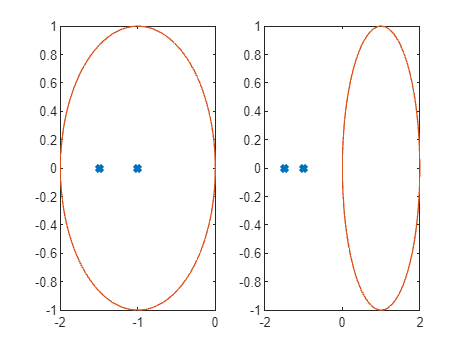


%Newton coles syms
%eig_val = eig(A)

figure
subplot(1, 2, 1)
plot(real(eig_val), imag(eig_val), 'x' , LineWidth=3)
hold on;
theta = linspace(0, 2*pi, 100);
x0_e = -1;
v = 1;
x = x0_e + v*cos(theta);
y = v*sin(theta);
plot(x, y)
hold off;

subplot(1, 2, 2)
plot(real(eig_val), imag(eig_val), 'x' , LineWidth=3)
hold on;
theta = linspace(0, 2*pi, 100);
x0_e = 1;
v = 1;
x = x0_e + v*cos(theta);
y = v*sin(theta);
plot(x, y)



disp("isstable_NewtonColess")

isstable_NewtonColess


disp("eig should have negative re")

eig should have negative re


eig(A)

ans =    -2.0000
   -3.0000


x_forw = [];
x_forw(:, 1) = x0;
x_back = [];
x_back(:, 1) = x0;
x_NC = [];
x_NC(:, 1) = x0;
for i = 1:i_max
    %x_forw(:, i+1) = euler_forw(A, h, x_forw(:, i));
    x_back(:, i+1) = euler_back(A, h, x_back(:, i));
    %x_NC(:, i+1) = NewtonColes(A, h, x_NC(:, i));
end

figure
hold on;
%stairs(t_numh, x_forw(1, :))
stairs(t_numh, x_back(2, :))
%stairs(t_numh, x_NC(1, :))
plot(t, y_num(1, :))
legend(["forw", "back", "Newton-Coles", "analityc"])

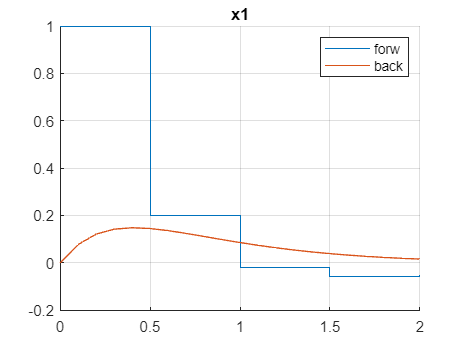

title("x1")
grid on;
hold off;